# calibra_anatomical

Reorient the obtained data so that they coincide approximately with the anatomical axes. 

Taking as a base a signal, in which the initial instants the only acceleration is that of gravity, it calculates the rotation matrix that realigns the reference axes so that the accelerations correspond to the antero-posterior, mid-lateral and vertical axes.

## Syntax

`Mrot=calibra_antomical (Acc_static);`

`Mrot=calibra_antomical (Acc_static, R_approx);`

## Description

- `Mrot=calibra_antomical (Acc_static);`

The input parameter, Acc_static is a matrix with the accelerations recorded in a static position used for calibration. It must be an nx3 matrix. 


$$\mathrm{acc}\;\mathrm{static}=\left\lbrack \begin{array}{ccc}
a_{\mathrm{x1}\;}  & a_{\mathrm{y1}}  & a_{\mathrm{z1}} \\
a_{\mathrm{x2}}  & a_{\mathrm{y2}}  & a_{\mathrm{z2}} \\
\ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp 
\end{array}\right\rbrack$$


When computing the rotation matrix, it is assumed that the sensor has been placed in the **standar orientation, **and the measured accelerations are close to be : 

column 1= vertical axis acceleration

column 2=medio lateral axis with changed sign acceleration

column 3= anteroposterior axis acceleration

 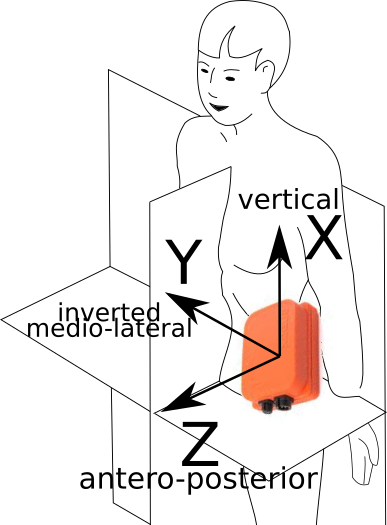

Output parameters Mrot - Rotation matrix that transforms the initial data to the anatomical axes.  If sensor data stores as columns of a matrix (nx3), the way to obtain the data referred to the anatomical axes will be to make the multiplication:

       `dat_anat=(data_sensor*Mrot')`

       or 

       `dat_anat=(Mrot*sensor_data')'`

- `Mrot=calibra_antomical (Acc_static, R_approx);`

When the sensor is not placed in the **standar position, **an estimation of the initial orientation must be provided. The parameter `R_approx` can be used to provide this orientation in two different ways.

-  A vector can be given with three numbers, indicating in which column are placed the antero-posterior, medio-lateral and vertical accelerations, respectively. If any axis is inverted, it is put with a negative sign. So on, the **standar orientation** corresponds to [ 3 , -2 , 1 ]

-  An initial rotation matrix can be given to align the axes to leave them in the antero-posterior, medio-lateral and vertical order.

## Examples

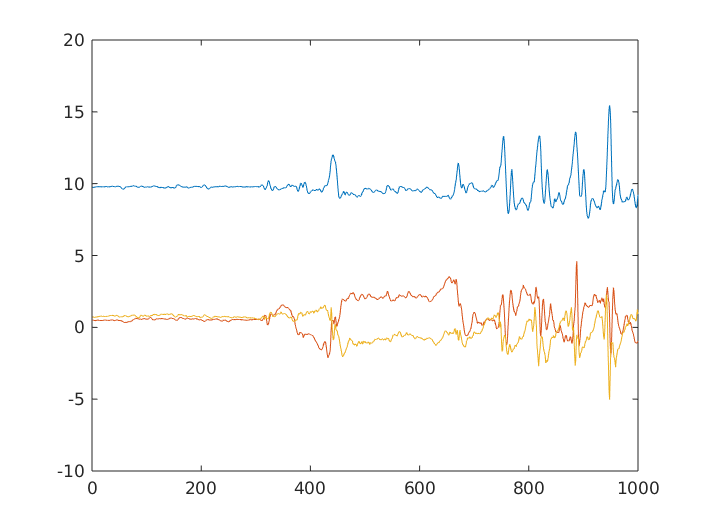

% Cargamos los datos de un experimento de calibracion ya conocido:
filename = '../simur_data/test.log';
data=load(filename);
acc=data(:,2:4);
%Dibujamos los 500 primeros datos de aceleración
plot(acc(1:1000,:));

%Los primeros 250 datos los usamos para calibración. Son estáticos.
%La primera columna se corresponde aproximadamente con la aceleración
%vertical
%La segunda columna se corresponde aproximadamente con la mediolateral
%cambiada de signo
%La tercera columna se corresponde aproximadamente con la anteroposterior

%Definimos la rotación previa como :
R=[ 3 , -2, 1]; %columna ap, columna ml, columna vert

% Matriz de calibracion:
Mrot=calibra_anatomical(acc(1:250,:), R)

Mrot =    -0.0967    0.5578    0.8243
         0   -0.8282    0.5604
    0.9953    0.0542    0.0801


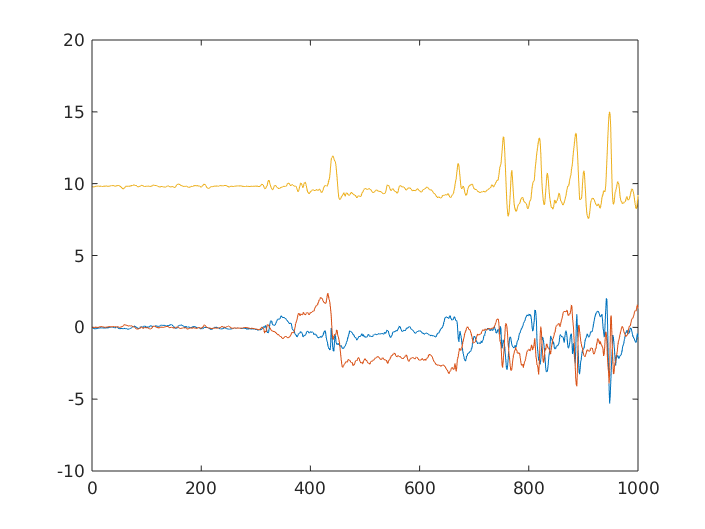

% Los datos calibrados son:
plot (acc(1:1000,:)*Mrot');

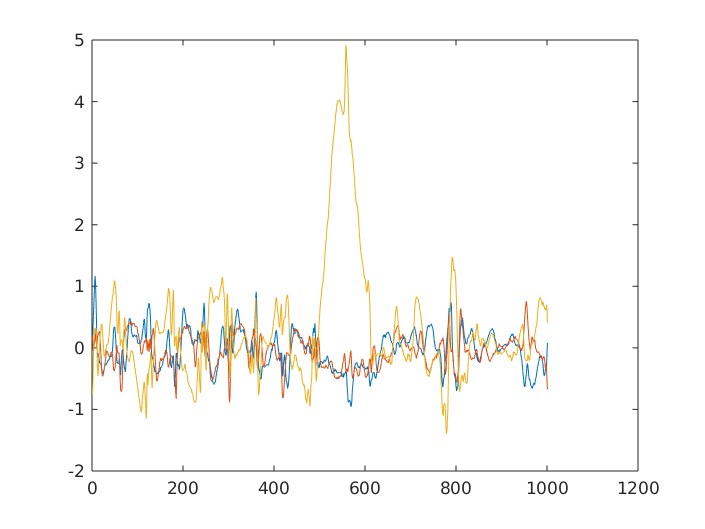

%Igualmente se calibran los giros o magnéticos
giro=data(:,5:7);
plot(giro(1500:2500,:)*Mrot');